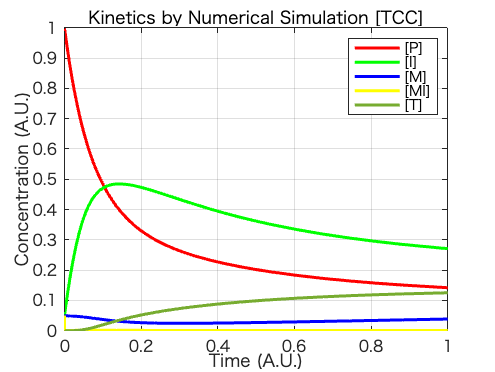

clc; clear; close all;



% Initial concentrations
P0 = 1;  % Initial concentration of P
I0 = 0.0;  % Initial concentration of I
M0 = 0.0;  % Initial concentration of M
MI0 = 0.05;  % Initial concentration of MI
MII0 = 0.0;  % Initial concentration of MII
DI0 = 0.0;
T0 = 0.00;  % Initial concentration of D
y0 = [P0; I0; M0; MI0; MII0; DI0; T0];

% Time span
tspan = [0 1.0];  % From t=0 to t=10

% Solve ODEs using ode15s
[t, y] = ode15s(@(t, y) reaction_odes(t, y), tspan, y0);

% Plot results
figure;
plot(t, y(:,1), 'r-', 'LineWidth', 2); hold on;
plot(t, y(:,2), 'g-', 'LineWidth', 2);
plot(t, y(:,3), 'b-', 'LineWidth', 2);
plot(t, y(:,4), 'y-', 'LineWidth', 2);
plot(t, y(:,7), 'LineWidth', 2);
xlabel('Time (A.U.)');
ylabel('Concentration (A.U.)');
legend('[P]', '[I]','[M]','[MI]','[T]');
title('Kinetics by Numerical Simulation [TCC]');
grid on;

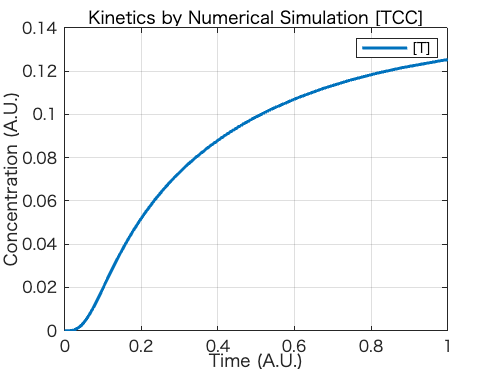


% Plot results
figure;
plot(t, y(:,7), 'LineWidth', 2);
xlabel('Time (A.U.)');
ylabel('Concentration (A.U.)');
legend('[T]');
title('Kinetics by Numerical Simulation [TCC]');
grid on;


% Function defining ODE system
function dydt = reaction_odes(~, y)
    P = y(1);
    I = y(2);
    M = y(3);
    MI = y(4);
    MII = y(5);
    DI = y(6);
    T = y(7);
% Define rate constants
% Intermediates [I], y(2) conc.
    k1=10;
    k1r=5;
    % Monomeric unit [M], y(3) conc.
    k2= 1;
    k2r=0.5;
    % Binding complex [MI], y(4) conc.
    k3=100000;
    k3r=1000000;
    % Binding complex [MI], y(4) conc.
    k4=1000000;
    k4r=1000000;
    % [2]Catenated unit (DCC) [D], y(5) conc.
    k5=1000;
    k5r= 10;

    
    dP_dt = - k1 * P + k1r * I;
    dI_dt = k1 * P - k1r * I - k2 * I^2 + k2r * M ...
        -k3 * I * M + k3r * MI - k4 * MI* I + k4r * MII...
        - k5 * (MII * I + DI * I) + k5r * (DI + T);
    dM_dt = k2 * I^2 - k2r * M - k3 * M * I + k3r * MI ;
    dMI_dt = k3 * M * I - k3r * MI - k4 * MI *I + k4r * MII; 
    dMII_dt = k4 * MI * I - k4r * MII - k5 * MII * I + k5r * DI;
    dDI_dt = k5 * MII * I - k5r * DI + k5r * T - k5 * DI *I;
    dT_dt = k5 * DI *I - k5r * T ;
    dydt = [dP_dt; dI_dt; dM_dt; dMI_dt; dMII_dt; dDI_dt; dT_dt];
end
